# Getting Started with MATLAB, Part 1

MATLAB is a high-performance technical computing language. The name MATLAB stands for Matrix Laboratory. This suggests that at its core MATLAB is a matrix centered programming language.

MATLAB allows matrix manipulations, plotting of functions and data, implementation of algorithms, creation of user interfaces, and interfacing with programs written in other languages, including C, C++, C#, Java, Fortran and Python.

clc;clear;

## Scalars and Vectors

We will start by creating the most basic type of element in MATLAB, the scalar.

a= 13

If you want to suppress the output on the screen we can add a semicolon to the end of our code statement.

a= 13;

Next we can construct a vector. 

A = [16 3 2]

You should notice that by default MATLAB creates a row vector. If you look at the output above you will see the dimension of the vector as (1x3). MATLAB is a row-major programing language which is convenient since this is how we think about indexing as economists.

You can verify the dimension of any element in MATLAB using the "size" function.

size(a)
size(A)

We can add elements to a vector.

A= [A a 1]

And we can delete an element from a vector.  In MATLAB we use parentheses to index. This is different from R and Python where we use brackets.

A(5)= [] 

We mentioned in the introduction that MATLAB is a matrix centered language. This means that MATLAB views most numerical objects as a matrix. For instance, when we ask MATLAB if "a", a scalar, is a matrix, MATLAB returns a logical value of 1 (TRUE) indicating that "a" is a matrix with dimension (1x1).

ismatrix(a)

We can do the same thing for a vector and MATLAB returns a logical value of 1 (TRUE) indicating that MATLAB also views a vector as a matrix, in our case a matrix with dimension (1x4).

ismatrix(A)

We can create a simple plot of "A".

plot(A)
grid on

MATLAB can make other graph types as well, with axis labels.

bar(A)
xlabel('x-axis')
ylabel('y-axis')

MATLAB can use symbols in plots as well. Here is an example using stars to mark the points. MATLAB offers a variety of other symbols and line types.

plot(A,'-*')
axis([0 5 0 20])

## Matrix

clc; clear;

Creating a matrix is as easy as making a vector, using semicolons (;) to separate the rows of a matrix.

A= [16 3 2 13; 5 10 11 8; 9 6 7 12; 4 15 14 1]

#### Sum, transpose and diag

If we want to sum the columns of a matrix.

sum(A)

When you do not specify an output variable, MATLAB uses the variable "ans", short for answer, to store the results of a calculation. You have computed a row vector containing the sums of the columns of A.

How about the row sums? MATLAB has a preference for working with the columns of a matrix, so the easiest way to get the row sums is to transpose the matrix, compute the column sums of the transpose, and then transpose the result. The transpose operation is denoted by an apostrophe or single quote, '. It flips a matrix about its main diagonal and it turns a row vector into a column vector.

A'
sum(A')'

produces a column vector containing the row sums.

The sum of the elements on the main diagonal is obtained with the sum and the diag functions:

diag(A)
sum(diag(A))

The other diagonal, the so-called antidiagonal, is not very important mathematically, so MATLAB does not have a ready-made function for it. But a function originally intended for use in graphics, fliplr, flips a matrix from left to right: 

sum(diag(fliplr(A)))

You may be starting to notice something unusual with the matrix "A". The column sums add to 34. The row sums add to 34. The diagonal and antidiagonal elements sum to 34. This is not strictly coincidental. This matrix property is known as a magic square.

This particular magic square appears in the [Renaissance engraving Melencolia I](https://www.metmuseum.org/en/art/collection/search/336228) by the German artist and amateur mathematician Albrecht Dürer.

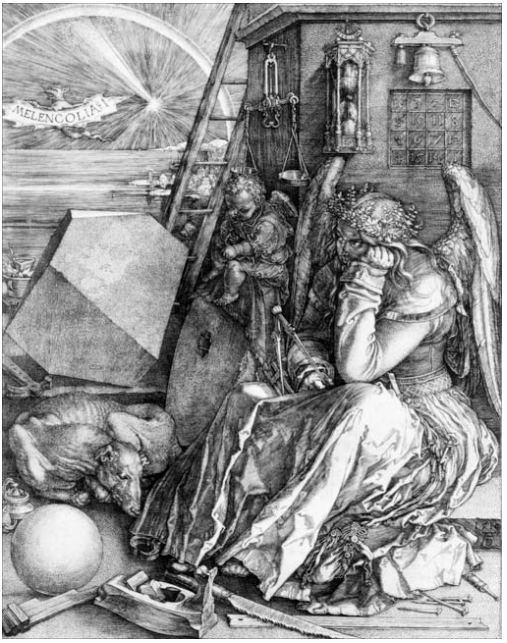

This image is filled with mathematical symbolism, and if you look carefully, you will see a matrix in the upper right corner. This matrix is known as a magic square and was believed by many in Dürer’s time to have genuinely magical properties. It does turn out to have some fascinating characteristics which we discovered above.

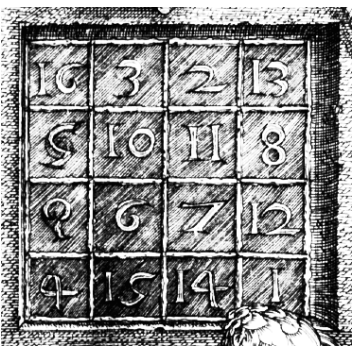

## Subscripts

The element in row i and column j of A is denoted by A(i,j). For example, A(4,2) is the number in the fourth row and second column. For our magic square, A(4,2) is 15. So to compute the sum of the elements in the fourth column of A, we can type 

A(1,4) + A(2,4) + A(3,4) + A(4,4)

It is also possible to refer the elements of a matrix with a single subscript, A(k). This is the usual way of referencing row and column vectors. But it can also apply to a fully two-dimensional matrix, in which case the array is regarded as one long column vector formed from the columns of the original matrix. So, for our magic square, A(8) is another way of referring to the value 15 stored in A(4,2). 

In the code box below try to extract the "A" matrix  third row, fourth column element using indexing.

If you try to use the value of an element outside of the matrix, it is an error:

t = A(4,5)

On the other hand, if you store a value in an element outside of the matrix, the size increases to accommodate the newcomer: 

X = A; 
X(4,5) = 17;
X

## The Colon Operator

The colon, : is one of the most important MATLAB operators. It occurs in several different forms.

We can sequence numbers 1 to 10 using the colon operator.

1:10

To obtain nonunit spacing, specify an increment. For example, 

100:-7:50

Subscript expressions involving colons refer to portions of a matrix: A(1:k,j) is the first k elements of the jth column of A. So 

sum(A(1:4,4)) 

computes the sum of the fourth column. But there is a better way. The colon by itself refers to all the elements in a row or column of a matrix and the keyword end refers to the last row or column. So

sum(A(:,end))

computes the sum of the elements in the last column of A:

## Expressions

Like most other programming languages, MATLAB provides mathematical expressions, but unlike most programming languages, these expressions involve entire matrices.

#### Variables

MATLAB does not require any type declarations or dimension statements. When MATLAB encounters a new variable name, it automatically creates the variable and allocates the appropriate amount of storage. If the variable already exists, MATLAB changes its contents and, if necessary, allocates new storage. For example,

num_students = 25

 creates a 1-by-1 matrix named num_students and stores the value 25 in its single element. We saw this 1x1 construction earlier.

Variable names consist of a letter, followed by any number of letters, digits, or underscores. MATLAB uses only the first 31 characters of a variable name. MATLAB is case sensitive; it distinguishes between uppercase and lowercase letters. A and a are not the same variable. To view the matrix assigned to any variable, simply enter the variable name.

#### Numbers

MATLAB uses conventional decimal notation, with an optional decimal point and leading plus or minus sign, for numbers. Scientific notation uses the letter e to specify a power-of-ten scale factor. Imaginary numbers use either i or j as a suffix but as applied economists we are not very often concerned with imaginary numbers. 

All numbers are stored internally using the long format specified by the IEEE floating-point standard. Floating-point numbers have a finite precision of roughly 16 significant decimal digits and a finite range of roughly $10^{-308}$ to $10^{+308}$.

#### Operators 

Expressions use familiar arithmetic operators and precedence rules.

For example, MATLAB will act as an expensive calculator using all standard operator notation.

(1+1) 
(1*2)
(4/2)
4*(1/2)
(1/2)^(-1)

#### Functions

MATLAB provides a large number of standard elementary mathematical functions, including abs, sqrt, exp, and sin. Taking the square root or logarithm of a negative number is not an error; the appropriate complex result is produced automatically. MATLAB also provides many more advanced mathematical functions, including Bessel and gamma functions. Most of these functions accept complex arguments. For a list of the elementary mathematical functions, type help elfun

For a list of more advanced mathematical and matrix functions, type "help specfun" and "help elmat"

Some of the functions, like sqrt and sin, are built in. Built-in functions are part of the MATLAB core so they are very efficient, but the computational details are not readily accessible. Other functions, like gamma and sinh, are implemented in M-files. 

There are some differences between built-in functions and other functions. For example, for built-in functions, you cannot see the code. For other functions, you can see the code and even modify it if you want. 

Several special functions provide values of useful constants. For example,

pi
i
realmin % Smallest floating-point number (realmax)
Inf % Infinity
NaN % Not-a-number
exp(1)
log(1) % Logarithm base e

Infinity is generated by dividing a nonzero value by zero, or by evaluating well defined mathematical expressions that overflow, i.e., exceed realmax. Not-a-number is generated by trying to evaluate expressions like 0/0 or Inf-Inf that do not have well defined mathematical values.

100/ 0
100/ 1e-306
100/ 1e-307

#### Function that Generate Special Matrices

Z= zeros(2,4)
F= ones(3,3)
F_twos= 2* ones(3,3) 
RU= rand(10, 10) % random uniform, Unif(0,1)
RN= randn(10,10) % random normal, N(0,1)
r = normrnd(3,10, [10,10]) % random normal, N(3,10)

## Loading data into MATLAB

The load function reads binary files containing matrices generated by earlier MATLAB sessions, or reads text files containing numeric data. The text file should be organized as a rectangular table of numbers, separated by blanks, with one row per line, and an equal number of elements in each row. For example, outside of MATLAB, create a text file (using the above requirements) containing the elements of our magic square from "A". Save this text file to your class folder that you created in your MATLAB directory. Save the text file as "magicSquare.txt". Then load this file into MATLAB by typing "load magicSquare.txt

You should have a variable called magicSquare that contains the matrix from your text file. To verify, you can look in the Workspace window or simply type the variable name in the Command Window below. If the variable magicSquare exists then you will see the matrix displayed, if not, then you will get an error telling you "Undefined function or variable".

Try typing a variable name below that does not exist in your Workspace.

You can read a csv file into MATLAB using the "readtable" command. CSV stands for comma-separated values. I suggest when working with table data you always save your files using the csv file format. This is similar to saving you text as a txt file, in that, txt and csv files are invariant to software programs, software versions, and operating systems. This means that if Microsoft Excel changes versions and you have saved your data as an xls file, there is a chance you will not be able to recover your data. This is most relevant with archived data but the concern is real. An additional value of saving your table data as a csv file is that you can share your data with anyone and you do not have to worry about their ability to read the data, csv is a universal file format.

T= readtable("dataMatrix_10000.csv")

If you have data in an Excel file format you can read this into MATLAB. Try looking at the help documents for the readtable function for more information.

We can also load any MATLAB code that has been saved into an M-file.  Use the MATLAB Editor or another text editor to create a file containing the same statements you would type at the MATLAB command line. Save the file under a name that ends in .m. 

For example, I have saved a simple file to perform an OLS regression using matrix algebra. We will learn how to use matrix algebra in MATLAB soon. I can run this code and import the results by simply calling the name of the file at the MATLAB Command Window,

ols

Open the file named "ols.m" in MATLAB. You will see the code that was run in the background when we typed "ols" at the command prompt.

####  Concatenation 

Concatenation is the process of joining small matrices to make bigger ones. In fact, you made your first matrix by concatenating its individual elements. The pair of square brackets, [], is the concatenation operator. For an example, start with the 4x4 magic square, and form a matrix that results in an 8x8 matrix. Load he magic square text file we created earlier.

Try to play around with the elements of the above matrix. For example, add a scalar to all elements of one of the magicSquare matrices or divide another matrix by "pi".

####  Deleting Rows and Columns

You can delete rows and columns from a matrix using just a pair of square brackets. Start with renaming the magicSquare matrix. Let's call it "A" again.

A= magicSquare

Now, to delete the second column of "A", 

A(:,2) = []

If you delete a single element from a matrix, the result is not a matrix anymore. So, expressions like

A(1,2) = []

result in an error. However, using a single subscript deletes a single element, or sequence of elements, and reshapes the remaining elements into a row vector. So 

A(2:2:10) = []

## Now lets just experiment with MATLAB

Open the "Getting Started with MATLAB, Python and R" cross-reference sheet located on the course website.

Look at the commands in section 5 (Basic Operators) and section 6 (Basic vector construction). Choose some commands that we have not explicitly discussed and type them into the Command Window to see what happens. If there is a command you are not familiar with and you want to learn more about it, type "help" and the function name. 

The only way to learn is by doing, so go and do...

## References

Works, M. (2005). Getting Started with MATLAB, Version 7. *MA: Math Works*.